%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 3);

% Specify sheet and range
opts.Sheet = "Data";
opts.DataRange = "A5:C1773";

% Specify column names and types
opts.VariableNames = ["Date", "DailyAverage", "dayAverage"];
opts.VariableTypes = ["datetime", "double", "double"];

% Import the data
SystemPrices = readtable("CarbonCosting\electricitypricesdataset071124v2.xlsx", opts, "UseExcel", false);
%% Clear temporary variables
clear opts


%% Import data from text file

opts = delimitedTextImportOptions("NumVariables", 33);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ["\t", " ", ",", ";", "_"];

% Specify column names and types
opts.VariableNames = ["DATETIME", "Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "INTENSITY", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33"];
opts.SelectedVariableNames = ["DATETIME", "INTENSITY"];
opts.VariableTypes = ["datetime", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "double", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3", "Var4", "Var5", "Var6", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "DATETIME", "InputFormat", "yyyy-MM-dd", "DatetimeFormat", "preserveinput");

% Import the data
CarbonOfGrid = readtable("CarbonCosting\df_fuel_ckan.csv", opts);

%% Clear temporary variables
clear opts

%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 3);

% Specify sheet and range
opts.Sheet = "Data";
opts.DataRange = "A6:C146";

% Specify column names and types
opts.VariableNames = ["Var1", "Dates", "Prices"];
opts.SelectedVariableNames = ["Dates", "Prices"];
opts.VariableTypes = ["char", "datetime", "double"];

% Specify variable properties
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto");

% Import the data
MonthlyElectricityPrices = readtable("CarbonCosting\monthly-electricity-prices-2013-2024.xlsx", opts, "UseExcel", false);


%% Clear temporary variables
clear opts


%% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 3);

% Specify sheet and range
opts.Sheet = "Data";
opts.DataRange = "A6:C102";

% Specify column names and types
opts.VariableNames = ["Var1", "Dates", "Prices"];
opts.SelectedVariableNames = ["Dates", "Prices"];
opts.VariableTypes = ["char", "datetime", "double"];

% Specify variable properties
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto");

% Import the data
MonthlyGasPrices = readtable("CarbonCosting\monthly-gas-prices-2016-2024.xlsx", opts, "UseExcel", false);


%% Clear temporary variables
clear opts



 % Example data for one year (365 days * 24 hours)


startDate = datetime('2020-01-01');
endDate = datetime('2023-12-31');
dates = startDate:endDate;
dates(dates == datetime(2020, 02, 29)) = [];
dates = dateshift(dates, 'start', 'day');
months = unique(dateshift(dates, 'start', 'month'));

dates.Format = 'yyyy-MM-dd';

HistoricCarbonIntensityOfGrid = zeros(length(dates),1);

datesfromcarbon = CarbonOfGrid.DATETIME;
datesfromcarbon = dateshift(datesfromcarbon, 'start', 'day');

[isMatch, idxMatch] = ismember(dates,datesfromcarbon);

for i=1:(length(idxMatch)-1)
    HistoricCarbonIntensityOfGrid(i) = mean(CarbonOfGrid.INTENSITY(idxMatch(i):(idxMatch(i+1)-1)));
end
HistoricCarbonIntensityOfGrid(length(idxMatch)) = mean(CarbonOfGrid.INTENSITY(idxMatch(length(idxMatch)):idxMatch(length(idxMatch))+48));


HistoricSellingPricesOfElectricity = zeros(length(dates),1); % in pence
HistoricBuyingPricesOfElectricity = zeros(length(months),1); % in pence
HistoricGasPricesOfElectricity = zeros(length(months),1); % in pence

DatesFromSystemPrices = SystemPrices.Date;
DatesFromElectricityPrices = MonthlyElectricityPrices.Dates;
DatesFromGasPrices = MonthlyGasPrices.Dates;

% Electricity System Prices (Selling Prices) - pence per kwh

[SystemDatesisMatch, SystemDatesidxMatch] = ismember(dates, DatesFromSystemPrices);

SystemDatesmatchedDates = dates(SystemDatesisMatch);
SystemDatesmatchingIndicesInData = SystemDatesidxMatch(SystemDatesisMatch);

HistoricSellingPricesOfElectricity(SystemDatesisMatch) = (SystemPrices.DailyAverage(SystemDatesmatchingIndicesInData))/100;

% Electricity Buying Prices - pence per kwh

[BuyingDatesisMatch, BuyingDatesidxMatch] = ismember(months, DatesFromElectricityPrices);

BuyingDatesmatchedDates = months(BuyingDatesisMatch);
BuyingDatesmatchingIndicesInData = BuyingDatesidxMatch(BuyingDatesisMatch);

HistoricBuyingPricesOfElectricity(BuyingDatesisMatch) = MonthlyElectricityPrices.Prices(BuyingDatesmatchingIndicesInData)/1000;

% Gas Buying Prices - pence per kwh

[GasDatesisMatch, GasDatesidxMatch] = ismember(months, DatesFromGasPrices);

GasDatesmatchedDates = months(GasDatesisMatch);
GasDatesmatchingIndicesInData = GasDatesidxMatch(GasDatesisMatch);

HistoricGasPricesOfElectricity(GasDatesisMatch) = MonthlyGasPrices.Prices(GasDatesmatchingIndicesInData)/29.3/100;

% Seasonal ARIMA Modelling

HistoricStartDate = datetime('2020-01-01');
HistoricEndDate = datetime('2023-12-31');
HistoricDates = HistoricStartDate:HistoricEndDate;
HistoricDates(HistoricDates == datetime(2020, 02, 29)) = [];
HistoricMonths = unique(dateshift(HistoricDates, 'start', 'month'));

FutureStartDate = datetime('2024-01-01');
FutureEndDate = datetime('2050-12-31');
FutureDates = FutureStartDate:FutureEndDate;
isFeb29 = (month(FutureDates) == 2) & (day(FutureDates) == 29);
FutureDates(isFeb29) = [];
FutureMonths = unique(dateshift(FutureDates, 'start', 'month'))

FutureMonths = 1×324 datetime array
   01-Jan-2024   01-Feb-2024   01-Mar-2024   01-Apr-2024   01-May-2024   01-Jun-2024   01-Jul-2024   01-Aug-2024   01-Sep-2024   01-Oct-2024   01-Nov-2024   01-Dec-2024   01-Jan-2025   01-Feb-2025   01-Mar-2025   01-Apr-2025   01-May-2025   01-Jun-2025   01-Jul-2025   01-Aug-2025   01-Sep-2025   01-Oct-2025   01-Nov-2025   01-Dec-2025   01-Jan-2026   01-Feb-2026   01-Mar-2026   01-Apr-2026   01-May-2026   01-Jun-2026   01-Jul-2026   01-Aug-2026   01-Sep-2026   01-Oct-2026   01-Nov-2026   01-Dec-2026   01-Jan-2027   01-Feb-2027   01-Mar-2027   01-Apr-2027   01-May-2027   01-Jun-2027   01-Jul-2027   01-Aug-2027   01-Sep-2027   01-Oct-2027   01-Nov-2027   01-Dec-2027   01-Jan-2028   01-Feb-2028   01-Mar-2028   01-Apr-2028   01-May-2028   01-Jun-2028   01-Jul-2028   01-Aug-2028   01-Sep-2028   01-Oct-2028   01-Nov-2028   01-Dec-2028   01-Jan-2029   01-Feb-2029   01-Mar-2029   01-Apr-2029   01-May-2029   01-Jun-2029   01-Jul-2029   01-Aug-2029   01-Sep-20


DatesNumForecastPeriods = length(FutureDates);
MonthsNumForecastPeriods = length(FutureMonths);

SellingPriceTs = timeseries(HistoricSellingPricesOfElectricity, 1:length(HistoricDates));
BuyingPriceTs = timeseries(HistoricBuyingPricesOfElectricity, 1:length(HistoricMonths));
GasPriceTs = timeseries(HistoricGasPricesOfElectricity, 1:length(HistoricMonths));
CarbonTs = timeseries(HistoricCarbonIntensityOfGrid, 1:length(HistoricDates));

% Fit an ARIMA model to the data
SellingPriceModel = arima('Constant',0.0032,'D',0,'Seasonality',365);  % ARIMA(1,1,1) model (AutoRegressive(1), Integrated(1), Moving Average(1))
SellingPriceFitModel = estimate(SellingPriceModel, SellingPriceTs.Data);

 
    ARIMA(0,0,0) Model Seasonally Integrated (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue
                ________    _____________    __________    ______

    Constant      0.0032              0           Inf        0   
    Variance    0.013479     0.00028632        47.078        0   




BuyingPriceModel = arima('Constant',0.0032,'D',0,'Seasonality',12);  % ARIMA(1,1,1) model (AutoRegressive(1), Integrated(1), Moving Average(1))
BuyingPriceFitModel = estimate(BuyingPriceModel, BuyingPriceTs.Data);

 
    ARIMA(0,0,0) Model Seasonally Integrated (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant      0.0032              0           Inf               0
    Variance    0.011944      0.0023058        5.1801      2.2174e-07




GasPriceModel = arima('Constant',0.0032,'D',0,'Seasonality',12);  % ARIMA(1,1,1) model (AutoRegressive(1), Integrated(1), Moving Average(1))
GasPriceFitModel = estimate(GasPriceModel, GasPriceTs.Data);

 
    ARIMA(0,0,0) Model Seasonally Integrated (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant       0.0032              0           Inf               0
    Variance    0.0015094     0.00029583        5.1021      3.3588e-07




CarbonModel = arima('D',0,'Seasonality',365);  % ARIMA(1,1,1) model (AutoRegressive(1), Integrated(1), Moving Average(1))
CarbonFitModel = estimate(CarbonModel, CarbonTs.Data);

 
    ARIMA(0,0,0) Model Seasonally Integrated (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue   
                _______    _____________    __________    ___________

    Constant    -2.7296       1.6987         -1.6069          0.10808
    Variance     4112.4       133.21          30.871      2.9561e-209




[SellingPriceYF, SellingPriceYMSE] = forecast(SellingPriceFitModel, DatesNumForecastPeriods, 'Y0', SellingPriceTs.Data);
[BuyingPriceYF, BuyingPriceYMSE] = forecast(BuyingPriceFitModel, MonthsNumForecastPeriods, 'Y0', BuyingPriceTs.Data);
[GasPriceYF, GasPriceYMSE] = forecast(GasPriceFitModel, MonthsNumForecastPeriods, 'Y0', GasPriceTs.Data);
[CarbonYF, CarbonYMSE] = forecast(CarbonFitModel, DatesNumForecastPeriods, 'Y0', CarbonTs.Data);

% Putting Value into Monthly

% Monthly Wind & Electrical Powers

% Step 1: Define the year
years = 2020:2023;
FutureYears = 2024:2050;

% Step 2: Get months and number of days in each month
months = 1:12; % Months from January 2020 to December 2023
daysInMonth = zeros(1, 12); % Initialize an array to hold the number of days
for m = months
    daysInMonth(m) = eomday(years(4), m); % Get the number of days in the month
end
daysInMonth(2) = 28;

% Step 3: Display the results
monthNames = month(datetime(years(4), months, 1), 'name'); % Get month names
index = 1;

MonthlyHistoricSellingPricesOfElectricity = zeros(1, length(HistoricMonths));
MonthlyFutureSellingPricesOfElectricity = zeros(1, length(FutureMonths));
MonthlyHistoricCarbonIntensityOfElectricity = zeros(1, length(HistoricMonths));
MonthlyFutureCarbonIntensityOfElectricity = zeros(1, length(FutureMonths));

for k=1:length(years)
    for i=1:length(months)
        PerMonthHistoricSellingPricesOfElectricity = 0;
        PerMonthHistoricCarbonIntensityOfElectricity = 0;
        for j=1:daysInMonth(i)
            PerMonthHistoricSellingPricesOfElectricity = PerMonthHistoricSellingPricesOfElectricity + HistoricSellingPricesOfElectricity(index);
            PerMonthHistoricCarbonIntensityOfElectricity = PerMonthHistoricCarbonIntensityOfElectricity + HistoricCarbonIntensityOfGrid(index);

            index = index + 1;
        end
        MonthlyHistoricSellingPricesOfElectricity((k-1)*12+i) = PerMonthHistoricSellingPricesOfElectricity/daysInMonth(i);
        MonthlyHistoricCarbonIntensityOfElectricity((k-1)*12+i) = PerMonthHistoricCarbonIntensityOfElectricity/daysInMonth(i);
    end
end

index = 1;

for k=1:length(FutureYears)
    for i=1:length(months)
        PerMonthFutureSellingPricesOfElectricity = 0;
        PerMFutureCarbonIntensityOfElectricity = 0;
        for j=1:daysInMonth(i)
            PerMonthFutureSellingPricesOfElectricity = PerMonthFutureSellingPricesOfElectricity + SellingPriceYF(index);
            PerMFutureCarbonIntensityOfElectricity = PerMFutureCarbonIntensityOfElectricity + CarbonYF(index);

            index = index + 1;
        end
        MonthlyFutureSellingPricesOfElectricity((k-1)*12+i) = PerMonthFutureSellingPricesOfElectricity/daysInMonth(i);
        MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i) = PerMFutureCarbonIntensityOfElectricity/daysInMonth(i);
    end
end



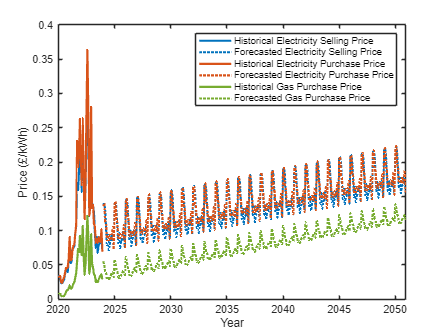

% Plot the historical data and forecasted values
figure;
%fontsize(gca,24,"pixels");
ax = gca;

hold on;
plot(HistoricMonths, MonthlyHistoricSellingPricesOfElectricity,'color',[0 0.4470 0.7410], 'LineWidth', 2);  % Historical data in blue
plot(FutureMonths, MonthlyFutureSellingPricesOfElectricity,'color',[0 0.4470 0.7410],'LineStyle',':', 'LineWidth', 2);  % Forecasted data in red

plot(HistoricMonths, HistoricBuyingPricesOfElectricity,'color',[0.8500 0.3250 0.0980], 'LineWidth', 2);  % Historical data in blue
plot(FutureMonths, BuyingPriceYF,'color',[0.8500 0.3250 0.0980],'LineStyle',':', 'LineWidth', 2);  % Forecasted data in red

plot(HistoricMonths, HistoricGasPricesOfElectricity,'color',[0.4660 0.6740 0.1880], 'LineWidth', 2);  % Historical data in blue
plot(FutureMonths, GasPriceYF,'color',[0.4660 0.6740 0.1880],'LineStyle',':', 'LineWidth', 2);  % Forecasted data in red

ylabel('Price (£/kWh)')%,'Interpreter','latex')%,FontSize=28);
box on
hold off

legend('Historical Electricity Selling Price', ...
    'Forecasted Electricity Selling Price', ...
    'Historical Electricity Purchase Price', ...
    'Forecasted Electricity Purchase Price', ...
    'Historical Gas Purchase Price', ...
    'Forecasted Gas Purchase Price')

xlabel('Year')%,FontSize=28);

%ax = gca;
print(gcf, 'Prices.eps', '-depsc');

%exportgraphics(ax,'Prices.eps','Resolution',300) 

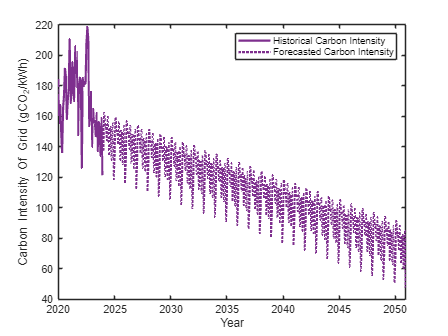

% Plot the historical data and forecasted values
figure;
%fontsize(gca,24,"pixels");
ax = gca;

hold on;
plot(HistoricMonths, MonthlyHistoricCarbonIntensityOfElectricity,'color',[0.4940 0.1840 0.5560], 'LineWidth', 2);  % Historical data in blue
plot(FutureMonths, MonthlyFutureCarbonIntensityOfElectricity,'color',[0.4940 0.1840 0.5560],'LineStyle',':', 'LineWidth', 2);  % Forecasted data in red

ylabel('Carbon Intensity Of Grid (gCO_2/kWh)')%,FontSize=28);
box on
hold off

legend('Historical Carbon Intensity',...
    'Forecasted Carbon Intensity ');

xlabel('Year')%,FontSize=28);

%ax = gca;
print(gcf, 'Carbon.eps', '-depsc');

%exportgraphics(ax,'Carbon.eps','Resolution',300) 


BuildingTab = load("..\Final Models and Data\CurrentBuildingVariables.mat");

NewBuildingTab = load("..\Final Models and Data\NewBuildingVariables.mat");

%%%NATHAN SET THIS CORRECTLTY
GridValues = load("..\Final Models and Data\GridValues.mat");

%Solar energy profile
WindTab = load("..\Final Models and Data\WindVariables.mat");
SolarTab = load("..\Final Models and Data\SolarVariables.mat");

BuildingTab.HourlyElectricalLoad(:,"29-Feb-2024: Thursday") = [];
BuildingTab.HourlyHeatingLoad(:,"29-Feb-2024: Thursday") = [];
BuildingTab.HourlyCoolingLoad(:,"29-Feb-2024: Thursday") = [];
NewBuildingTab.HourlyElectricalLoad(:,"29-Feb-2024: Thursday") = [];
NewBuildingTab.HourlyHeatingLoad(:,"29-Feb-2024: Thursday") = [];
NewBuildingTab.HourlyCoolingLoad(:,"29-Feb-2024: Thursday") = [];

% Money & Carbon calcs setup

Columns = ["Solar","Wind","GSHP","Battery","Windows","Insulation","SCWF","Heat Recovery", "LEDs"];
Rows = ["Number of Items", "CAPEX per Item", "Total CAPEX", ...
    "Total OPEX Per Year", "OPEX until 2050", ...
    "Total OPEX until 2050","Total Cost of Ownership", "Energy Produced/Saved Per Year", ...
    "Total Energy Produced/Saved Per Year", "Total Energy Produced/Saved until 2050",...
    "LCOE/LCOS","Carbon Intensity",...
    "Carbon Footprint", "Carbon Abatement Cost"];

MoneyAndCarbonTable = {}; %array2table(MoneyAndCarbonArray,'RowNames',Rows,'VariableNames',Columns);

% Number of Items
MoneyAndCarbonTable(1,:) = {1000, 18, 1, 1, ...
    140, 1142.4, 280, 1, 1293.6};

%CAPEX per Item
MoneyAndCarbonTable(2,:) = {500.00,1500.00,0,0,...
    1240.00,55.95,32.50,22000.00,50.00};

%Total CAPEX
MoneyAndCarbonTable(3,:) = num2cell(cell2mat(MoneyAndCarbonTable(1,:)).*cell2mat(MoneyAndCarbonTable(2,:)));
MoneyAndCarbonTable(3,3) = num2cell(679000.00); 
MoneyAndCarbonTable(3,4) = num2cell(2129472.00);
%CAPEX per Item
MoneyAndCarbonTable(2,:) = num2cell(cell2mat(MoneyAndCarbonTable(3,:))./cell2mat(MoneyAndCarbonTable(1,:)));

%Total OPEX Per Year
MoneyAndCarbonTable(4,:) = {0,0,460,7.89*4800,...
    0,0,0,1800,0};
MoneyAndCarbonTable(4,1) = num2cell(15*cell2mat(MoneyAndCarbonTable(1,1)));
MoneyAndCarbonTable(4,2) = num2cell(0.02*cell2mat(MoneyAndCarbonTable(3,2)));

%SCWF calc from original building/revit
SCWF = zeros(24,365);
0.5 .* 8494; 

% Given value to split
value = 0.5 .* 8494;

% Size of the 2D array
rows = 365;
cols = 24;

% Create a 2D array of the desired size and split the value equally
SCWF = value * ones(rows, cols) / (rows * cols);

%Energy Produced/Saved Per Year
items = [
    {table2array(SolarTab.RoofHourlySolarEnergy) + table2array(SolarTab.QuadHourlySolarEnergy) + table2array(SolarTab.WallHourlySolarEnergy)},...
    {table2array(WindTab.HourlySavoniusWind) .* 9 .* 0.5},...
    {table2array(BuildingTab.HourlyHeatingLoad)},...
    {table2array(GridValues.HourlyBatteryPower)},...
    {0.15 .* (table2array(BuildingTab.HourlyHeatingLoad) + table2array(BuildingTab.HourlyCoolingLoad))},...
    {0.07 .* (table2array(BuildingTab.HourlyHeatingLoad) + table2array(BuildingTab.HourlyCoolingLoad))},...
    {SCWF},...
    {0.15 .* (table2array(BuildingTab.HourlyHeatingLoad) + table2array(BuildingTab.HourlyCoolingLoad))},...
    {0.2 .* table2array(BuildingTab.HourlyElectricalLoad)}
];

%Energy Produced/Saved Per Year
MoneyAndCarbonTable(8,:) = items;

InterestRate = 1.032;
OPEX25 = zeros(25,length(Columns));
OPEX25(1,:) = cell2mat(MoneyAndCarbonTable(4,:));
for i=2:27
     OPEX25(i,:) = OPEX25(i-1,:).*InterestRate;
end

OPEX25(15,4) = OPEX25(15,4) + 2129472.00/2;

for i=1:9
    %Total Energy Produced/Saved Per Year
    MoneyAndCarbonTable(9,i) = num2cell(sum(sum(cell2mat(MoneyAndCarbonTable(8,i)),2),1));
    %Total Energy Produced/Saved until 2050
    MoneyAndCarbonTable(10,i) = num2cell(cell2mat(MoneyAndCarbonTable(9,i)).*27);
    %OPEX until 2050
    MoneyAndCarbonTable(5,i) = {OPEX25(:,i)};
    %Total OPEX until 2050
    MoneyAndCarbonTable(6,i) = num2cell(sum(OPEX25(:,i)));
    %Total Cost of Ownership
    MoneyAndCarbonTable(7,i) = num2cell(cell2mat(MoneyAndCarbonTable(3,i))+cell2mat(MoneyAndCarbonTable(6,i)));
end

%LCOE/LCOS
MoneyAndCarbonTable(11,:) = num2cell(cell2mat(MoneyAndCarbonTable(7,:))./cell2mat(MoneyAndCarbonTable(10,:)));

% To Do: Carbon Intensity, Carbon Footprint & Carbon Abatement

%Carbon Intensity
MoneyAndCarbonTable(12,1) = {149.3};
MoneyAndCarbonTable(12,2) = {26.57};
MoneyAndCarbonTable(12,4) = {196000*2};

%Carbon Footprint
MoneyAndCarbonTable(13,:) = num2cell([0, 0, 3916000,0, 48400, 0, 0, 390000, 125000].*cell2mat(MoneyAndCarbonTable(1,:)));
MoneyAndCarbonTable(13,1) = num2cell(149.3.*cell2mat(MoneyAndCarbonTable(9,1)));
MoneyAndCarbonTable(13,2) = num2cell(26.57.*cell2mat(MoneyAndCarbonTable(9,2)));
MoneyAndCarbonTable(13,4) = num2cell(19000.*cell2mat(MoneyAndCarbonTable(9,4)));
MoneyAndCarbonTable(12,:) = num2cell(cell2mat(MoneyAndCarbonTable(13,:))./cell2mat(MoneyAndCarbonTable(9,:)));

%Carbon Abatement - pound per gco2e footprint
%MoneyAndCarbonTable(14,:) = num2cell(cell2mat(MoneyAndCarbonTable(13,:)) ./ cell2mat(MoneyAndCarbonTable(10,:)));

colours = [[0 0.4470 0.7410],
    [0.8500 0.3250 0.0980],
    [0.9290 0.6940 0.1250],
    [0.4940 0.1840 0.5560],
    [0.4660 0.6740 0.1880],
    [0.3010 0.7450 0.9330],
    [0.6350 0.0780 0.1840]];

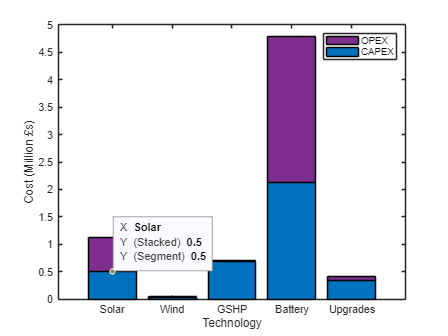

figure;
CAPEX = cell2mat(MoneyAndCarbonTable(3,1:4));
OPEX = cell2mat(MoneyAndCarbonTable(6,1:4));
CAPEX = [CAPEX sum(cell2mat(MoneyAndCarbonTable(3,5:end)))];
OPEX = [OPEX sum(cell2mat(MoneyAndCarbonTable(6,5:end)))];
Groups = [Columns(1:4) "Upgrades"];

hold on
h = bar(Groups,[CAPEX' OPEX']/1000000,'stacked');

h(1).FaceColor = colours(1,:);
h(2).FaceColor = colours(4,:);

%bar(Columns,OPEX,'stacked');
%ytickformat('%,.0f');
hold off
box on

legend(["CAPEX","OPEX"]);
%fontsize(gca,39,"pixels");
ax = gca;
%ax.YAxis.Exponent = 0;
ylim([ax.YAxis.Limits(1),ax.YAxis.Limits(2)])
%ytickformat('%,.0f');
ylabel("Cost (Million £s)")%,FontSize=42);
xlabel("Technology")%,FontSize=42);

print(gcf, 'CAPEXOPEX.eps', '-depsc');

%exportgraphics(ax,'CAPEXOPEX.eps','Resolution',300) 

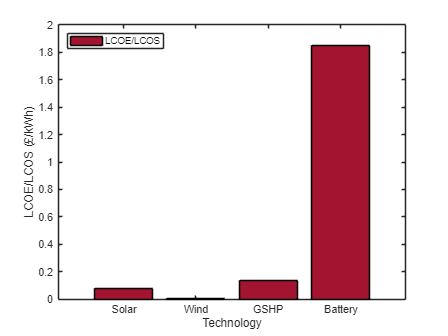

figure;
LCOE = cell2mat(MoneyAndCarbonTable(11,1:4));
hold on
h = bar(Columns(1:4),LCOE);

h(1).FaceColor = colours(7,:);

%bar(Columns,OPEX,'stacked');
%ytickformat('%,.0f');
hold off
box on

legend("LCOE/LCOS",'Location','northwest');
%fontsize(gca,39,"pixels");
ax = gca;
%ax.YAxis.Exponent = 0;
ylim([ax.YAxis.Limits(1),ax.YAxis.Limits(2)])
%ytickformat('%,.0f');
ylabel("LCOE/LCOS (£/kWh)")%,FontSize=42);
xlabel("Technology")%,FontSize=42);

print(gcf, 'LCOE.eps', '-depsc');

%exportgraphics(ax,'LCOE.eps','Resolution',300, 'ContentType', 'vector') 

% Money & Carbon calcs - grid/gas only relevance

OldDailyElectricalLoad = sum(table2array(BuildingTab.HourlyElectricalLoad),1);
NewDailyElectricalLoad = sum(table2array(NewBuildingTab.HourlyElectricalLoad),1);
OldDailyHeatingLoad= sum(table2array(BuildingTab.HourlyHeatingLoad),1);
NewDailyHeatingLoad= sum(table2array(NewBuildingTab.HourlyHeatingLoad),1);
OldDailyCoolingLoad= sum(table2array(BuildingTab.HourlyCoolingLoad),1);
NewDailyCoolingLoad= sum(table2array(NewBuildingTab.HourlyCoolingLoad),1);

DailySCWF = sum(SCWF,2);

DailySavoniusPower = sum(table2array(WindTab.HourlySavoniusWind),1);
DailySolarPowerWithQuad = sum(table2array(SolarTab.WallHourlySolarEnergy + SolarTab.RoofHourlySolarEnergy + SolarTab.QuadHourlySolarEnergy),1);

DailyGridUsage = sum(table2array(GridValues.HourlyUsedGridPower),1);
DailyGridSelling = sum(table2array(GridValues.HourlyReturnedGridPower),1);
DailyBattery = sum(table2array(GridValues.HourlyBatteryPower),1);

OriginalElectricityUse = 1095999;
OriginalGasUse = 1111162;
GasCarbonIntensity = 185;%g / kWh

ExistingGasCarbon = 25*OriginalGasUse*185;

% Putting Value into Monthly

OldMonthlyElectricity = zeros(1, 12);
NewMonthlyElectricity = zeros(1, 12);
OldMonthlyHeating = zeros(1, 12);
NewMonthlyHeating = zeros(1, 12);
OldMonthlyCooling = zeros(1, 12);
NewMonthlyCooling = zeros(1, 12);

MonthlySCWF = zeros(1, 12);

MonthlyWindPower = zeros(1, 12);
MonthlySolarPowerWithQuad = zeros(1,12);

MonthlyGridUsage = zeros(1, 12);
MonthlyGridSelling = zeros(1,12);
MonthlyBattery = zeros(1,12);

index = 1;

for i=1:length(months)
    OldPerMonthElecLoad = 0;
    NewPerMonthElecLoad = 0;
    OldPerMonthHeatLoad = 0;
    NewPerMonthHeatLoad = 0;
    OldPerMonthCoolLoad = 0;
    NewPerMonthCoolLoad = 0;
    PerMonthSCWF = 0;
    PerMonthWind = 0;
    PerMonthSolarWithQuad = 0;
    PerMonthGridUsage = 0;
    PerMonthGridSelling = 0;
    PerMonthBattery = 0;
    for j=1:daysInMonth(i)
        OldPerMonthElecLoad = OldPerMonthElecLoad + OldDailyElectricalLoad(index);
        NewPerMonthElecLoad = NewPerMonthElecLoad + NewDailyElectricalLoad(index);
        OldPerMonthHeatLoad = OldPerMonthHeatLoad + OldDailyHeatingLoad(index);
        NewPerMonthHeatLoad = NewPerMonthHeatLoad + NewDailyHeatingLoad(index);
        OldPerMonthCoolLoad = OldPerMonthCoolLoad + OldDailyCoolingLoad(index);
        NewPerMonthCoolLoad = NewPerMonthCoolLoad + NewDailyCoolingLoad(index);
        
        PerMonthSCWF = PerMonthSCWF + DailySCWF(index);

        PerMonthWind = PerMonthWind + DailySavoniusPower(index)*18*0.5;
        PerMonthSolarWithQuad = PerMonthSolarWithQuad + DailySolarPowerWithQuad(index);
        
        PerMonthGridUsage = PerMonthGridUsage + DailyGridUsage(index);
        PerMonthGridSelling = PerMonthGridSelling + DailyGridSelling(index);
        PerMonthBattery = PerMonthBattery + DailyBattery(index);

        index = index + 1;
    end
    OldMonthlyElectricity(i) = OldPerMonthElecLoad;
    NewMonthlyElectricity(i) = NewPerMonthElecLoad;
    OldMonthlyHeating(i) = OldPerMonthHeatLoad;
    NewMonthlyHeating(i) = NewPerMonthHeatLoad;
    OldMonthlyCooling(i) = OldPerMonthCoolLoad;
    NewMonthlyCooling(i) = NewPerMonthCoolLoad;

    MonthlySCWF(i) = PerMonthSCWF;

    MonthlyWindPower(i) = PerMonthWind;
    MonthlySolarPowerWithQuad(i) = PerMonthSolarWithQuad;

    MonthlyGridUsage(i) = PerMonthGridUsage;
    MonthlyGridSelling(i) = PerMonthGridSelling;
    MonthlyBattery(i) = PerMonthBattery;
end

NormalisedHeatingLoad = NewMonthlyHeating./sum(NewMonthlyHeating);
MonthlyGasUsage = NormalisedHeatingLoad*OriginalGasUse;

MonthlyFutureExpenditureIfSolarBoughtOnGrid = zeros(1, length(FutureMonths));
MonthlyFutureExpenditureIfWindBoughtOnGrid = zeros(1, length(FutureMonths));
MonthlyFutureExpenditureIfGSHPBoughtOnGas = zeros(1, length(FutureMonths));
MonthlyFutureExpenditureIfBatteryBoughtOnGrid = zeros(1, length(FutureMonths));

MonthlyFutureExpenditureIfWindowsNotImplemented = zeros(1, length(FutureMonths));
MonthlyFutureExpenditureIfInsulationNotImplemented  = zeros(1, length(FutureMonths));
MonthlyFutureExpenditureIfSCWFNotImplemented  = zeros(1, length(FutureMonths));
MonthlyFutureExpenditureIfHeatRecoveryNotImplemented  = zeros(1, length(FutureMonths));
MonthlyFutureExpenditureIfLEDsNotImplemented  = zeros(1, length(FutureMonths));

MonthlyFutureBuyingFromGrid = zeros(1, length(FutureMonths));
MonthlyFutureIfFullyReliantOnGrid = zeros(1, length(FutureMonths));
MonthlyFutureIfChangesNotImplemented = zeros(1, length(FutureMonths));
MonthlyFutureEarningsFromGrid = zeros(1, length(FutureMonths));
MonthlyFutureIfFullyReliantOnGas = zeros(1, length(FutureMonths));
MonthlyFutureIfChangesNotImplementedGas = zeros(1, length(FutureMonths));

MonthlyFutureCarbonSavingsOfSolar = zeros(1, length(FutureMonths));
MonthlyFutureCarbonSavingsOfWind = zeros(1, length(FutureMonths));
MonthlyFutureCarbonSavingsOfBattery = zeros(1, length(FutureMonths));
MonthlyFutureCarbonSavingsOfGSHP = zeros(1, length(FutureMonths));

MonthlyFutureCarbonSavingsOfWindows = zeros(1, length(FutureMonths));
MonthlyFutureCarbonSavingsOfInsulation = zeros(1, length(FutureMonths));
MonthlyFutureCarbonSavingsOfSCWF = zeros(1, length(FutureMonths));
MonthlyFutureCarbonSavingsOfHeatRecovery = zeros(1, length(FutureMonths));
MonthlyFutureCarbonSavingsOfLEDs = zeros(1, length(FutureMonths));

MonthlyFutureCarbonOfGrid = zeros(1, length(FutureMonths));
MonthlyFutureCarbonOfGridIfFullyResilantOnGrid = zeros(1, length(FutureMonths));
MonthlyFutureCarbonOfGridIfChangesNotImplemented = zeros(1, length(FutureMonths));
MonthlyFutureGridCarbonEmissionsSaved = zeros(1, length(FutureMonths));

for k=1:length(FutureYears)
    for i=1:length(months)
        MonthlyFutureExpenditureIfSolarBoughtOnGrid((k-1)*12+i) = MonthlySolarPowerWithQuad(i)*BuyingPriceYF((k-1)*12+i);
        MonthlyFutureExpenditureIfWindBoughtOnGrid((k-1)*12+i) = MonthlyWindPower(i)*BuyingPriceYF((k-1)*12+i);
        MonthlyFutureExpenditureIfGSHPBoughtOnGas((k-1)*12+i) = MonthlyGasUsage(i)*GasPriceYF((k-1)*12+i);
        MonthlyFutureExpenditureIfBatteryBoughtOnGrid((k-1)*12+i) = MonthlyBattery(i)*BuyingPriceYF((k-1)*12+i);

        MonthlyFutureExpenditureIfWindowsNotImplemented((k-1)*12+i) = 0.15*(OldMonthlyHeating(i) + OldMonthlyCooling(i))/4*BuyingPriceYF((k-1)*12+i);
        MonthlyFutureExpenditureIfInsulationNotImplemented((k-1)*12+i)  = 0.07*(OldMonthlyHeating(i) + OldMonthlyCooling(i))/4*BuyingPriceYF((k-1)*12+i);
        MonthlyFutureExpenditureIfSCWFNotImplemented((k-1)*12+i)  = MonthlySCWF(i)*BuyingPriceYF((k-1)*12+i);
        MonthlyFutureExpenditureIfHeatRecoveryNotImplemented((k-1)*12+i)  = 0.15*(OldMonthlyHeating(i) + OldMonthlyCooling(i))/4*BuyingPriceYF((k-1)*12+i);
        MonthlyFutureExpenditureIfLEDsNotImplemented((k-1)*12+i)  = 0.2*(OldMonthlyElectricity(i))*BuyingPriceYF((k-1)*12+i);

        MonthlyFutureBuyingFromGrid((k-1)*12+i) = MonthlyGridUsage(i)*BuyingPriceYF((k-1)*12+i);
        MonthlyFutureIfFullyReliantOnGrid((k-1)*12+i) = NewMonthlyElectricity(i)*BuyingPriceYF((k-1)*12+i);
        MonthlyFutureIfChangesNotImplemented((k-1)*12+i) = OldMonthlyElectricity(i)*BuyingPriceYF((k-1)*12+i);
        MonthlyFutureEarningsFromGrid((k-1)*12+i) = MonthlyGridSelling(i)*MonthlyFutureSellingPricesOfElectricity((k-1)*12+i);
        
        MonthlyFutureIfFullyReliantOnGas((k-1)*12+i) = (NewMonthlyHeating(i) + NewMonthlyCooling(i))*GasPriceYF((k-1)*12+i);
        MonthlyFutureIfChangesNotImplementedGas((k-1)*12+i) = (OldMonthlyHeating(i) + OldMonthlyCooling(i))*GasPriceYF((k-1)*12+i);

        MonthlyFutureCarbonSavingsOfSolar((k-1)*12+i) = MonthlySolarPowerWithQuad(i)*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
        MonthlyFutureCarbonSavingsOfWind((k-1)*12+i) = MonthlyWindPower(i)*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
        MonthlyFutureCarbonSavingsOfGSHP((k-1)*12+i) = MonthlyGasUsage(i)*GasCarbonIntensity;
        MonthlyFutureCarbonSavingsOfBattery((k-1)*12+i) = MonthlyBattery(i)*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);

        MonthlyFutureCarbonSavingsOfWindows((k-1)*12+i) = 0.15*(OldMonthlyHeating(i) + OldMonthlyCooling(i))/4*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
        MonthlyFutureCarbonSavingsOfInsulation((k-1)*12+i) = 0.07*(OldMonthlyHeating(i) + OldMonthlyCooling(i))/4*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
        MonthlyFutureCarbonSavingsOfSCWF((k-1)*12+i) = MonthlySCWF(i)*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
        MonthlyFutureCarbonSavingsOfHeatRecovery((k-1)*12+i) = 0.15*(OldMonthlyHeating(i) + OldMonthlyCooling(i))/4*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
        MonthlyFutureCarbonSavingsOfLEDs((k-1)*12+i) = 0.2*(OldMonthlyElectricity(i))*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);

        MonthlyFutureCarbonOfGrid((k-1)*12+i) = MonthlyGridUsage(i)*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
        MonthlyFutureCarbonOfGridIfFullyResilantOnGrid((k-1)*12+i) = NewMonthlyElectricity(i)*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
        MonthlyFutureCarbonOfGridIfChangesNotImplemented((k-1)*12+i) = OldMonthlyElectricity(i)*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
        MonthlyFutureGridCarbonEmissionsSaved((k-1)*12+i) = MonthlyGridSelling(i)*MonthlyFutureCarbonIntensityOfElectricity((k-1)*12+i);
    end
end


% Energy price conversions from pence to pounds

%Savings
SolarSavings = sum(MonthlyFutureExpenditureIfSolarBoughtOnGrid) ;

WindSavings = sum(MonthlyFutureExpenditureIfWindBoughtOnGrid) ;

GSHPSavings = sum(MonthlyFutureExpenditureIfGSHPBoughtOnGas) ;

BatterySavings = sum(MonthlyFutureExpenditureIfBatteryBoughtOnGrid) ;
 
WindowsSavings = sum(MonthlyFutureExpenditureIfWindowsNotImplemented) ;

InsulationSavings = sum(MonthlyFutureExpenditureIfInsulationNotImplemented) ;

SCWFSavings = sum(MonthlyFutureExpenditureIfSCWFNotImplemented) ;

HeatRecoverySavings = sum(MonthlyFutureExpenditureIfHeatRecoveryNotImplemented) ;

LEDsSavings = sum(MonthlyFutureExpenditureIfLEDsNotImplemented) ;

TotalSavings = sum([SolarSavings,WindSavings,GSHPSavings,BatterySavings...
    ,WindowsSavings,InsulationSavings,SCWFSavings,HeatRecoverySavings,LEDsSavings]) ;

MonetarySavings = [SolarSavings WindSavings GSHPSavings BatterySavings WindowsSavings...
    InsulationSavings SCWFSavings HeatRecoverySavings LEDsSavings TotalSavings];

PurchasedFromGridMoney = sum(MonthlyFutureBuyingFromGrid);
IfFullyReliantOnGridMoney = sum(MonthlyFutureIfFullyReliantOnGrid)

IfFullyReliantOnGridMoney = 3.3837e+06

IfNoUpgradesPurchasedFromGridMoney = sum(MonthlyFutureIfChangesNotImplemented);
SoldToGridMoney = sum(MonthlyFutureEarningsFromGrid);

IfFullyReliantOnGasMoney = sum(MonthlyFutureIfFullyReliantOnGas)

IfFullyReliantOnGasMoney = 7.1136e+05

IfNoUpgradesPurchasedFromGasMoney = sum(MonthlyFutureIfChangesNotImplementedGas);
% Cash Flows = Electricity Generation Income - Total Annual OPEX 

SolarCashFlow = sum(reshape(MonthlyFutureExpenditureIfSolarBoughtOnGrid,12, []), 1)  ...
    - cell2mat(MoneyAndCarbonTable(5,1))';

WindCashFlow = sum(reshape(MonthlyFutureExpenditureIfWindBoughtOnGrid,12, []), 1)  ...
    - cell2mat(MoneyAndCarbonTable(5,2))';

GSHPCashFlow = sum(reshape(MonthlyFutureExpenditureIfGSHPBoughtOnGas,12, []), 1)  ...
    - cell2mat(MoneyAndCarbonTable(5,3))';

BatteryCashFlow = sum(reshape(MonthlyFutureExpenditureIfBatteryBoughtOnGrid,12, []), 1)  ...
    - cell2mat(MoneyAndCarbonTable(5,4))';
 
WindowsCashFlow = sum(reshape(MonthlyFutureExpenditureIfWindowsNotImplemented,12, []), 1)  ...
    - cell2mat(MoneyAndCarbonTable(5,5))';

InsulationCashFlow = sum(reshape(MonthlyFutureExpenditureIfInsulationNotImplemented,12, []), 1)  ...
    - cell2mat(MoneyAndCarbonTable(5,6))';

SCWFCashFlow = sum(reshape(MonthlyFutureExpenditureIfSCWFNotImplemented,12, []), 1)  ...
    - cell2mat(MoneyAndCarbonTable(5,7))';

HeatRecoveryCashFlow = sum(reshape(MonthlyFutureExpenditureIfHeatRecoveryNotImplemented,12, []), 1)  ...
    - cell2mat(MoneyAndCarbonTable(5,8))';

LEDsCashFlow = sum(reshape(MonthlyFutureExpenditureIfLEDsNotImplemented,12, []), 1)  ...
    - cell2mat(MoneyAndCarbonTable(5,9))';

TotalCashFlow = sum(reshape(MonthlyFutureIfFullyReliantOnGrid,12, []), 1)  ...
    + sum(reshape(MonthlyFutureEarningsFromGrid,12, []), 1)  ...
    - sum(reshape(MonthlyFutureBuyingFromGrid,12, []), 1)  ...
    - sum(cell2mat(MoneyAndCarbonTable(5,:)),2)';

SolarCashFlow = [-cell2mat(MoneyAndCarbonTable(3,1)) SolarCashFlow];
WindCashFlow = [-cell2mat(MoneyAndCarbonTable(3,2)) WindCashFlow];
GSHPCashFlow = [-cell2mat(MoneyAndCarbonTable(3,3)) GSHPCashFlow];
BatteryCashFlow = [-cell2mat(MoneyAndCarbonTable(3,4)) BatteryCashFlow];

WindowsCashFlow = [-cell2mat(MoneyAndCarbonTable(3,5)) WindowsCashFlow];
InsulationCashFlow = [-cell2mat(MoneyAndCarbonTable(3,6)) InsulationCashFlow];
SCWFCashFlow = [-cell2mat(MoneyAndCarbonTable(3,7)) SCWFCashFlow];
HeatRecoveryCashFlow = [-cell2mat(MoneyAndCarbonTable(3,8)) HeatRecoveryCashFlow];
LEDsCashFlow = [-cell2mat(MoneyAndCarbonTable(3,9)) LEDsCashFlow];

TotalCashFlow = [-sum(cell2mat(MoneyAndCarbonTable(3,:))) TotalCashFlow];

%Cumulative CashFlows

SolarCumCashFlow = cumsum(SolarCashFlow);
WindCumCashFlow = cumsum(WindCashFlow);
GSHPCumCashFlow = cumsum(GSHPCashFlow);
BatteryCumCashFlow = cumsum(BatteryCashFlow);

WindowsCumCashFlow = cumsum(WindowsCashFlow);
InsulationCumCashFlow = cumsum(InsulationCashFlow);
SCWFCumCashFlow = cumsum(SCWFCashFlow);
HeatRecoveryCumCashFlow = cumsum(HeatRecoveryCashFlow);
LEDsCumCashFlow = cumsum(LEDsCashFlow);

TotalCumCashFlow = cumsum(TotalCashFlow);

%NPV

DiscountRate = 0.04;

SolarNPV = pvvar(SolarCashFlow,DiscountRate);
WindNPV = pvvar(WindCashFlow,DiscountRate);
GSHPNPV = pvvar(GSHPCashFlow,DiscountRate);
BatteryNPV = pvvar(BatteryCashFlow,DiscountRate);

WindowsNPV = pvvar(WindowsCashFlow,DiscountRate);
InsulationNPV = pvvar(InsulationCashFlow,DiscountRate);
SCWFNPV = pvvar(SCWFCashFlow,DiscountRate);
HeatRecoveryNPV = pvvar(HeatRecoveryCashFlow,DiscountRate);
LEDsNPV = pvvar(LEDsCashFlow,DiscountRate);

TotalNPV = pvvar(TotalCashFlow,DiscountRate);

NPV = [SolarNPV WindNPV GSHPNPV BatteryNPV WindowsNPV...
    InsulationNPV SCWFNPV HeatRecoveryNPV LEDsNPV TotalNPV];

%Payback Period
PaybackSolar = 1 + (0 - SolarCumCashFlow(1))/(SolarCumCashFlow(2) - SolarCumCashFlow(1));
PaybackWind = 1 + (0 - WindCumCashFlow(1))/(WindCumCashFlow(2) - WindCumCashFlow(1));
PaybackGSHP = 1 + (0 - GSHPCumCashFlow(1))/(GSHPCumCashFlow(2) - GSHPCumCashFlow(1));
PaybackBattery = 1 + (0 - BatteryCumCashFlow(1))/(BatteryCumCashFlow(2) - BatteryCumCashFlow(1));

PaybackWindows = 1 + (0 - WindowsCumCashFlow(1))/(WindowsCumCashFlow(2) - WindowsCumCashFlow(1));
PaybackInsulation = 1 + (0 - InsulationCumCashFlow(1))/(InsulationCumCashFlow(2) - InsulationCumCashFlow(1));
PaybackSCWF = 1 + (0 - SCWFCumCashFlow(1))/(SCWFCumCashFlow(2) - SCWFCumCashFlow(1));
PaybackHeatRecovery = 1 + (0 - HeatRecoveryCumCashFlow(1))/(HeatRecoveryCumCashFlow(2) - HeatRecoveryCumCashFlow(1));
PaybackLEDs = 1 + (0 - LEDsCumCashFlow(1))/(LEDsCumCashFlow(2) - LEDsCumCashFlow(1));

PaybackTotal = 1 + (0 - TotalCumCashFlow(1))/(TotalCumCashFlow(2) - TotalCumCashFlow(1));

Payback = [PaybackSolar PaybackWind PaybackGSHP PaybackBattery...
    PaybackWindows PaybackInsulation PaybackSCWF PaybackHeatRecovery PaybackLEDs PaybackTotal];
%Return on Investment

% Avoided Carbon Emissions

SolarCarbonSavings = sum(MonthlyFutureCarbonSavingsOfSolar);
WindCarbonSavings = sum(MonthlyFutureCarbonSavingsOfWind);
GSHPCarbonSavings = sum(MonthlyFutureCarbonSavingsOfGSHP);
BatteryCarbonSavings = sum(MonthlyFutureCarbonSavingsOfBattery);

WindowsCarbonSavings = sum(MonthlyFutureCarbonSavingsOfWindows);
InsulationCarbonSavings = sum(MonthlyFutureCarbonSavingsOfInsulation);
SCWFCarbonSavings = sum(MonthlyFutureCarbonSavingsOfSCWF);
HeatRecoveryCarbonSavings = sum(MonthlyFutureCarbonSavingsOfHeatRecovery);
LEDsCarbonSavings = sum(MonthlyFutureCarbonSavingsOfLEDs);

TotalCarbonSavings = sum(MonthlyFutureCarbonOfGridIfChangesNotImplemented);

CarbonSavings = [SolarCarbonSavings WindCarbonSavings GSHPCarbonSavings BatteryCarbonSavings WindowsCarbonSavings...
    InsulationCarbonSavings SCWFCarbonSavings HeatRecoveryCarbonSavings LEDsCarbonSavings TotalCarbonSavings];

%Carbon Abatement - pound per gco2e footprint
%MoneyAndCarbonTable(14,:) = num2cell(cell2mat(MoneyAndCarbonTable(13,:)) ./ cell2mat(MoneyAndCarbonTable(10,:)));

% New Carbon Emissions

PurchasedFromGridCarbon = sum(MonthlyFutureCarbonOfGrid);
IfFullyReliantOnGridCarbon = sum(MonthlyFutureCarbonOfGridIfFullyResilantOnGrid)

IfFullyReliantOnGridCarbon = 2.5939e+09

IfNoUpgradesPurchasedFromGridCarbon = sum(MonthlyFutureCarbonOfGridIfChangesNotImplemented);
SoldToGridCarbon = sum(MonthlyFutureGridCarbonEmissionsSaved);

IfFullyReliantOnGasCarbon = sum(MonthlyFutureCarbonSavingsOfGSHP)

IfFullyReliantOnGasCarbon = 5.5503e+09

IfNoUpgradesPurchasedFromGasCarbon = ExistingGasCarbon;